# Modelo SEIRS

**Universidad eafit**

**Segundo Semestre 2024**

**Sistemas lineales**

**Carlos M. Veléz S.**

**Luis M. Martinez G.**

**Sebastian A. Amaya C.**

## 1.El Modelo SIERS

El modelo SEIRS, una piedra angular de la epidemiología, divide las poblaciones en compartimentos susceptibles (S), expuestos (E), infecciosas (I), recuperadas (R) y nuevamente susceptibles (S), lo que proporciona un enfoque estructurado para estudiar la dinámica de transmisión de enfermedades. A través de ecuaciones diferenciales, rastrea el movimiento de los individuos entre estos compartimentos a lo largo del tiempo, lo que refleja las transiciones de la susceptibilidad a la exposición, la infección y, en última instancia, la recuperación o la susceptibilidad nuevamente.

La versatilidad de este modelo se extiende a diversas aplicaciones, incluida la predicción de la propagación de enfermedades, la evaluación de estrategias de intervención y la optimización de la asignación de recursos durante los brotes. Al simular diferentes escenarios, los investigadores y los responsables de la formulación de políticas pueden anticipar la trayectoria de las enfermedades infecciosas, evaluar la eficacia de las medidas de control y tomar decisiones informadas para mitigar su impacto en la salud pública.

Su marco matemático proporciona información sobre las tasas de transmisión, los períodos de latencia y la dinámica de la inmunidad, lo que permite a las partes interesadas implementar medidas proactivas y gestionar eficazmente los brotes de enfermedades dentro de las poblaciones.

### 1.1.Descripcion del modelo

La mayoría de las descripciones matemáticas de la dinámica poblacional de las enfermedades infecciosas se basan en la capacidad de dividir la población en compartimentos discretos que no se superponen para asi estudiar el flujo de los inidividuos atravez de las diferentes clasificaiones. Para este Modelo se estudian 4 compartimientos:

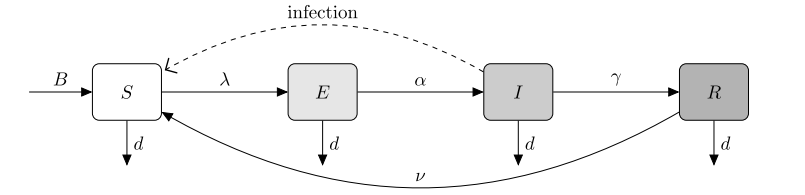

#### figura1

La figura 1 nos brinda un "esquema" del modelo y de la interaccion de entre las poblaciones del modelo de esta practica, es importante hacer clara ciertas consideraciones del modelo, primero, tomando una visión centrada en el patógeno, categorizamos al huésped (persona) por su estado con respecto al patógeno,Como las siglas del modelo indican los compartimientos en los que se divide la poblacion son:

- Suceptibles(S):Individuos que no han sido infectados por la enfermedad y que pueden contraerla si entran en contacto con personas infectadas

- Infeciosas(I):Individuos actualmente infectados con la enfermedad y que pueden transmitirla a otros susceptibles.

- Recuperados(R):Individuos que han sido infectados previamente pero ya se han recuperado de la enfermedad. Son inmunes y pueden volver a contraer la enfermedad.

- Expuestos(E): Individuos que han sido infectados con una enfermedad pero que aún no son contagiosos.

- Poblacion total (N): es la suma de todas las poblaciones anteriores

Ademas podemos observar que se considera una poblacion aislada y que la enfermdad modelada no es mortal, es decir la unica entrada de nuevos integrantes es mediante nacimientos  y la unica salida es mediante muerte por causas ajenas al patojeno, en la siguiente seccion se explicara con mayor detalle la dinamica del modelo.

### 1.2.VARIABLES Y PÁRAMETROS DEL MODELO

Se puede observar que se usan varios parametros para regular el flujo entre las diferentes poblaciones, acontinuacion se da una descripcion de de estas:

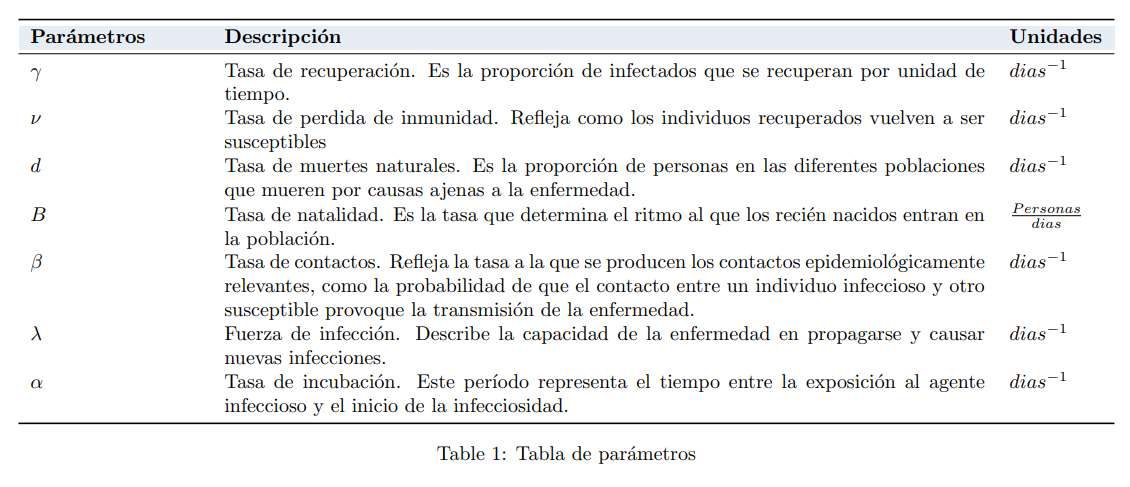

#### figura 2

### 1.3 Ecuaciones del modelo

Considerando la clasifiacion de la poblacion previamente establecida, las ecuaciones no lineales del modelo se pueden describir de la siguiente manera:

La población susceptible `(S)` varía con el tiempo `(t)`, aumentando con la llegada de recién nacidos `(B) `y los recuperados que pierden su inmunidad `(νR)`, y disminuyendo con los susceptibles que son infectados `(-λS)` y los que han muerto por causas naturales `(-dS)`.


$$\frac{\mathrm{dS} }{\mathrm{d} t}=B+\nu R-\lambda S-dS$$
  

La población expuesta `(E)` varía con el tiempo `(t)`, incrementando con los susceptibles que han sido infectados `(λS)` y disminuyendo con los individuos expuestos que incuban la enfermedad (se vuelven infecciosos) `(-αE)` y los expuestos que han fallecido por causas naturales `(-dE)`.


$$\frac{\mathrm{d} E}{\mathrm{d} t}=\lambda S -\alpha E-dE$$
  

La población infectada `(I)` varía con el tiempo `(t)`, aumentando con los individuos expuestos que incuban la enfermedad (se vuelven infecciosos) `(αE)`, y reduciendo con aquellos infectados que se han recuperado `(-γI) `o han fallecido por causas naturales `(-dI)`.


$$\frac{\mathrm{d} I }{\mathrm{d} t}=\alpha E - \gamma I-dI$$
 

La población recuperada `(R)` varía con el tiempo `(t)`, incrementando con los individuos infectados que se han recuperado `(γI)` y reduciendo con aquellos recuperados que pierden su inmunidad y se vuelven susceptibles de nuevo `(-νR)` y los recuperados que han fallecido por causas naturales `(-dR)`.


$$\frac{\mathrm{d} R }{\mathrm{d} t}= \gamma I-\nu R-dR$$


Debido a que el tamaño de nuestra poblacion es variable el valor de la fuerza de infeccion **(λ) **se actualiza constantemente


$$\lambda=\frac{\beta I}{N}$$


El modelo completo se compone de las siguientes 5 ecuaciones:

**(1) **$\frac{\mathrm{dS} }{\mathrm{d} t}=B+\nu R-\lambda S-dS$            

**(2) **$\frac{\mathrm{d} E}{\mathrm{d} t}=\lambda S -\alpha E-dE$                

**(3) **$\frac{\mathrm{d} I }{\mathrm{d} t}=\alpha E - \gamma I-dI$                 

**(4) **$\frac{\mathrm{d} R }{\mathrm{d} t}= \gamma I-\nu R-dR$                  

**(5) **$\lambda=\frac{\beta I}{N}$                                

### 1.4 hipotesis

Acontinuacion se plantean hipotsis de las estructuras encontradas en el proceso de identificacion del sistema:

- se espera indentificar un modelo de orden 4 debido a las caracteristicas ya conocidas del sistema, ademas ya que el modelo inicial es no lineal se espera una estructura con la capidad de replicar comportamientos complejos.

## 2.Metodos

En esta sección de métodos, se proporcionará una explicación de como se realiza la verificacion del sistema en Simulink. Se describirá  el proceso de realización de cada prueba en Simulink, desde la configuración hasta la interpretación de los resultados, ofreciendo una visión general del enfoque metodológico utilizado en este estudio. Ademas se explicara como se realizara un ejercicio de identificacion del sistema generando datos de la salida de la poblacion infectada con ruido (variaciones), esto se hace con el objetivo de simular como seria una identificacion del sistema en el campo.

### 2.1 MODELO VERIFICADO DEL SISTEMA EN SIMULINK

Se Realiza la verificacion del modelo al recrear la figura 3 de  [1] que representa el comportamiento del modelo SIERS, para cumplir este objetivo se realiza la simulacion con parametros que se enlistaran proximamente y se compara la simulacion con la grafica de referencia.

- ***β***=0.2

- `ν`=0.001

- ***α***=0.1

- `γ`=0.1

- `d`=0.0001

- `B`=0.0001

### 2.2 Resumen de los pasos para la Identificacion

El proceso se centra en la identificación de una estructura de modelo adecuada para representar el sistema. Los pasos son los siguientes:

- Introducción de Entrada Artificial:Dado que el modelo no cuenta con entradas, se añade una entrada artificial mediante la modificación del parámetro $\beta$, permitiendo la posterior identificación del sistema.

- Análisis de Linealidad y Selección del Punto de Operación: Se obtienen las curvas de linealidad y se selecciona un punto de operación y un rango para garantizar que el comportamiento del sistema sea capturado correctamente.

- Selección del Periodo de Muestreo: El periodo de muestreo se selecciona utilizando una entrada escalón, asegurando que las dinámicas del sistema sean capturadas adecuadamente.

- Generación de Datos con Ruido: Se introduce ruido en el modelo y se utilizan secuencias PRBS (Pseudo Random Binary Sequence) para obtener datos experimentales, necesarios para la identificación.

-  Identificación de Estructuras de Modelo: Se evalúan las estructuras ARX, ARMAX, OE y BJ, buscando la que mejor represente la dinámica del sistema.

- Selección de Modelos Candidatos: Los modelos se seleccionan con base en el análisis de residuos y ajuste de los datos experimentales.

- Validación del Modelo: Los modelos se validan con entradas escalón y senoidales para verificar su capacidad de replicar el comportamiento del sistema.

- Análisis de Polos y Ceros: Se analizan los polos y ceros del mejor modelo delos seleccionados, junto con sus intervalos de confianza.

- Optimización del Modelo: El modelo final se optimiza mediante un algoritmo de gradiente descendente, utilizando la estructura seleccionada (OE o ARX). 

## 3. Resultados

dir_modelo = "SEIRS_2_verificacion.slx";

### 3.1. Verificacion de Codigo

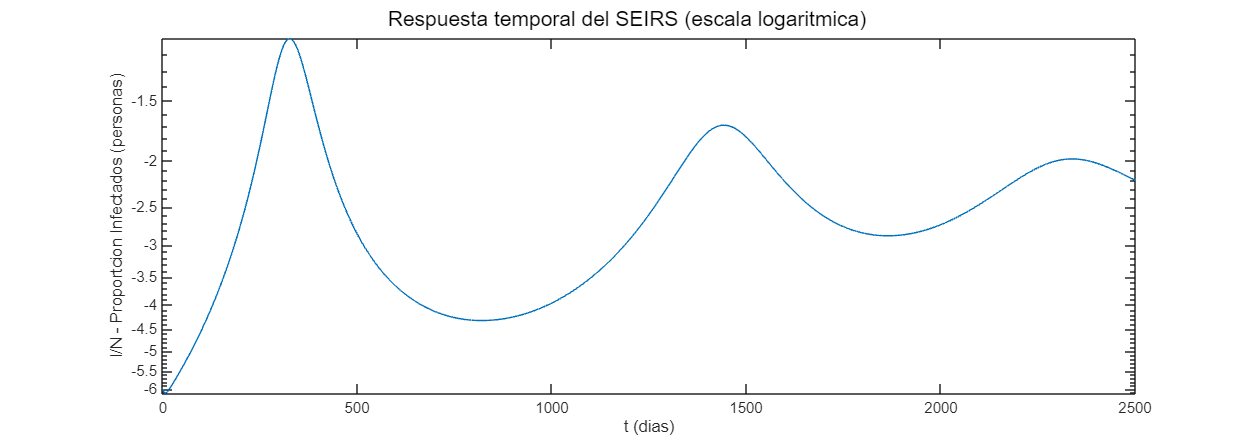

T=2500; 
x=zeros(1,6);
x(1)=0.0001; %B
x(2)=0.0001; %d
x(3)=0.1; %alpha_
x(4)=0.1; %gamma_
x(5)=0.2; %beta_
x(6)=0.001; %nu_
%N0_=[1-1e-6 1e-6 0 0]; 
beta_U=timetable(seconds(0),0);
simulacion_1_verificacion=sim(dir_modelo);
tiempo=simulacion_1_verificacion.tout;
infectados=simulacion_1_verificacion.infectados.signals.values;

h1 = figure;
subplot(1,1,1), plot(tiempo,infectados), xlabel('t (dias)'), ylabel('I/N - Proportcion Infectados (personas)')
set(h1,'Units','normalized','Position',[0 0 0.8 0.5]);
yscale log
sgtitle('Respuesta temporal del SEIRS (escala logaritmica)')

### 3.2. Linealizacion del modelo

#### 3.2.1 Linealizacion experimental

I=0:0.05:0.8;
T=10000;
var_init=zeros(1,6);
var_init(1)=0.0001; %B
var_init(2)=0.0001; %d
var_init(3)=0.1; %alpha_
var_init(4)=0.1; %gamma_
var_init(5)=0.2; %beta_dos;
var_init(6)=0.001; %nu_

dir_modelo = "SEIRS_Test.slx";
data_S=[];
data_E=[];
data_I=[];
data_R=[];
for i=I
    u=i;
    prueba_sim=sim(dir_modelo);
    data_S=[data_S,prueba_sim.S.signals.values(end)];
    data_E=[data_E,prueba_sim.E.signals.values(end)];
    data_I=[data_I,prueba_sim.I.signals.values(end)];
    data_R=[data_R,prueba_sim.R.signals.values(end)];
end

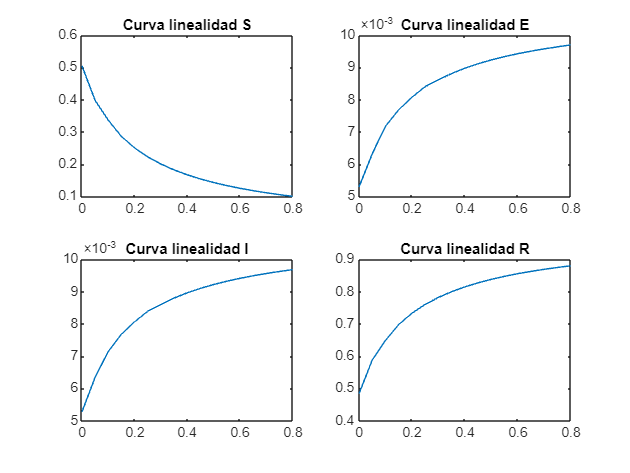

figure
subplot(2,2,1)
plot(I,data_S)
title('Curva linealidad S');
subplot(2,2,2);
plot(I,data_E)
title('Curva linealidad E');
subplot(2,2,3)
plot(I,data_I)
title('Curva linealidad I');
subplot(2,2,4)
plot(I,data_R)
title('Curva linealidad R');

### 3.3. Punto de muestreo

dir_modelo = "SEIRS_Test.slx";
u=0.6; %punto de operacion escogido
T=7000;
Sim_Punto_M=sim(dir_modelo);


S_M=Sim_Punto_M.S.signals.values;
E_M=Sim_Punto_M.E.signals.values;
I_M=Sim_Punto_M.I.signals.values;
R_M=Sim_Punto_M.R.signals.values;
t_M=Sim_Punto_M.I.time;
Funcion_yss= @(x,m) (x(end)-x(1))*m+x(1);


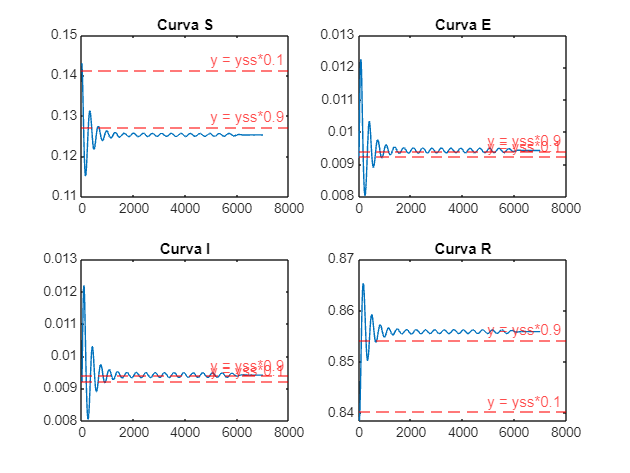


figure
subplot(2,2,1)
plot(t_M,S_M)
yline(Funcion_yss(S_M,0.9), 'r--', 'y = yss*0.9');
yline(Funcion_yss(S_M,0.1), 'r--', 'y = yss*0.1');

title('Curva S');
subplot(2,2,2);
plot(t_M,E_M)
yline(Funcion_yss(E_M,0.9), 'r--', 'y = yss*0.9');
yline(Funcion_yss(E_M,0.1), 'r--', 'y = yss*0.1');

title('Curva E');
subplot(2,2,3)
plot(t_M,I_M)
yline(Funcion_yss(I_M,0.9), 'r--', 'y = yss*0.9');
yline(Funcion_yss(I_M,0.1), 'r--', 'y = yss*0.1');

title('Curva I');
subplot(2,2,4)
plot(t_M,R_M)
yline(Funcion_yss(R_M,0.9), 'r--', 'y = yss*0.9');
yline(Funcion_yss(R_M,0.1), 'r--', 'y = yss*0.1');

title('Curva R');

syms tr ts
rango=tr/10<ts<tr/2

$$rango = \left(\frac{\mathrm{tr}}{10}<\mathrm{ts}\right)<\frac{\mathrm{tr}}{2}$$

rango=subs(rango,tr,int8(t_M(find(R_M<=Funcion_yss(R_M,0.9)*1.001 & R_M>=Funcion_yss(R_M,0.9)*0.999,1))))

$$rango = \left(\frac{89}{10}<\mathrm{ts}\right)<\frac{89}{2}$$

### 3.4 Generacion de datos con ruido

#### 3.4.1 verificacion de ruido con entrada escalera

T=18000;
Sim_ruido=sim("SEIRS_Ruido.slx");
S=Sim_ruido.S.signals.values;
E=Sim_ruido.E.signals.values;
I=Sim_ruido.I.signals.values;
R=Sim_ruido.R.signals.values;
t=Sim_ruido.I.time;

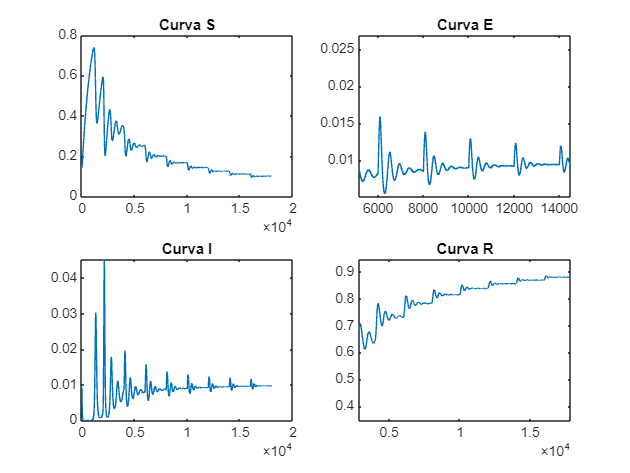

figure
subplot(2,2,1)
plot(t,S)
title('Curva S');
subplot(2,2,2);
plot(t,E)
title('Curva E');
subplot(2,2,3)
plot(t,I)
title('Curva I');
subplot(2,2,4)
plot(t,R)
title('Curva R');

#### 3.4.2 Generacion de datos con una entrada PRBS

T=20000;
var_init=zeros(1,6);
var_init(1)=0.0001; %B
var_init(2)=0.0001; %d
var_init(3)=0.1; %alpha_
var_init(4)=0.1; %gamma_
var_init(5)=0.2; %beta_dos;
var_init(6)=0.001; %nu_
Control_U=3;
time = (0:10:T)';
beta_U = timetable(seconds(time),zeros(numel(time),1));
beta_seno = timetable(seconds(time),zeros(numel(time),1));
Rango_PRBS=[0.5 0.7];
dir_modelo = "SEIRS_PRBS.slx";
Sim_Data=sim(dir_modelo);

Y=Sim_Data.I.signals.values;
U=Sim_Data.Entrada_U.signals.values;
t=Sim_Data.I.time;


#### 3.4.3 Generacion de datos con una entrada escalon

T=20000;
var_init=zeros(1,6);
var_init(1)=0.0001; %B
var_init(2)=0.0001; %d
var_init(3)=0.1; %alpha_
var_init(4)=0.1; %gamma_
var_init(5)=0.2; %beta_dos;
var_init(6)=0.001; %nu_
u=0.6;
Control_U=1;
time = (0:10:T)';
beta_U = timetable(seconds(time),(time>=2500)*0.1+0.6);
beta_seno = timetable(seconds(time),zeros(numel(time),1));
dir_modelo = "SEIRS_PRBS.slx";
Sim_Data_Escalon=sim(dir_modelo);

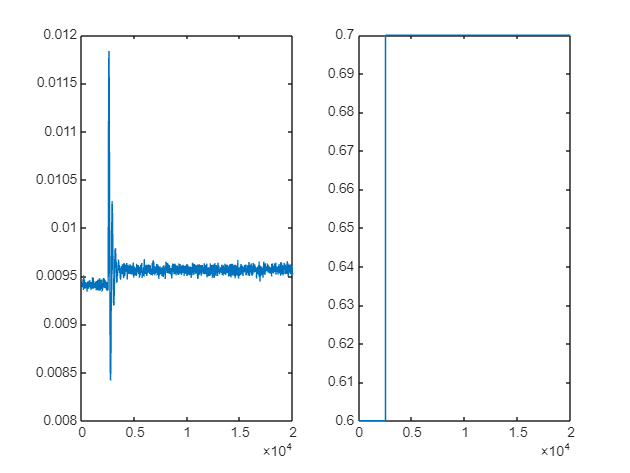


Infectados_Escalon=Sim_Data_Escalon.I.signals.values;
Entrada_Escalon=Sim_Data_Escalon.Entrada_U.signals.values;
t_entrada=Sim_Data_Escalon.Entrada_U.time;
t_escalon=Sim_Data_Escalon.I.time;
Y_Escalon=Infectados_Escalon;
U_Escalon=Entrada_Escalon;

figure
subplot(1,2,1)
plot(t_escalon,Infectados_Escalon)
subplot(1,2,2)
plot(t_entrada,Entrada_Escalon)

#### 3.4.6 Generacion de datos con una entrada  sinusoidal.

T=20000;
var_init=zeros(1,6);
var_init(1)=0.0001; %B
var_init(2)=0.0001; %d
var_init(3)=0.1; %alpha_
var_init(4)=0.1; %gamma_
var_init(5)=0.2; %beta_dos;
var_init(6)=0.001; %nu_
u=0.6;
Control_U=2;
time = (0:10:T)';
beta_U =timetable(seconds(time),zeros(numel(time),1));
beta_seno=timetable(seconds(time),-sin(time*2*pi/5000)*0.1 +0.6);
dir_modelo = "SEIRS_PRBS.slx";
Sim_Data_Escalon=sim(dir_modelo);

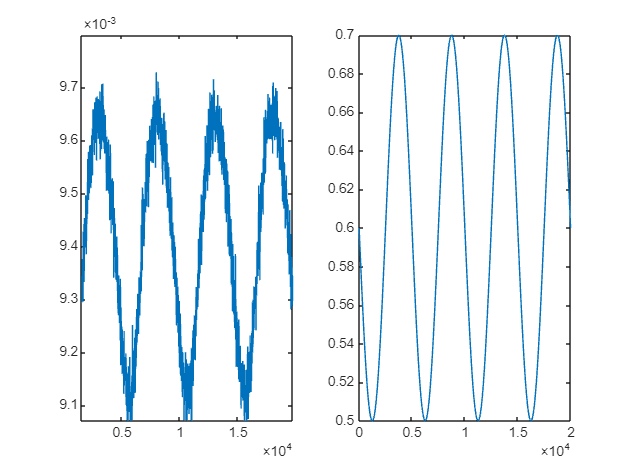


Infectados_Seno=Sim_Data_Escalon.I.signals.values;
Entrada_Seno=Sim_Data_Escalon.Entrada_U.signals.values;
t_entrada=Sim_Data_Escalon.Entrada_U.time;
t_escalon=Sim_Data_Escalon.I.time;
Y_Seno=Infectados_Seno;
U_Seno=Entrada_Seno;
figure
subplot(1,2,1)
plot(t_escalon,Infectados_Seno)
subplot(1,2,2)
plot(t_entrada,Entrada_Seno)

### 3.5 Grafico de seleccion de retardo

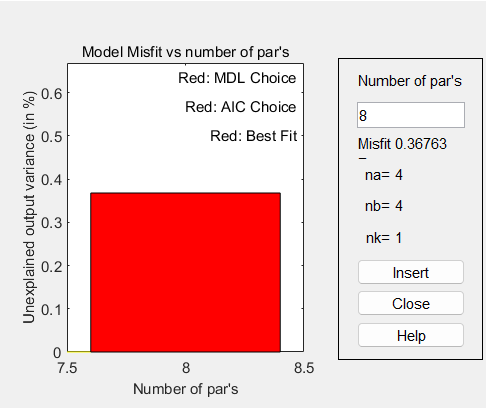

### 3.6 Gráfico de la función de coste para varias estructuras.

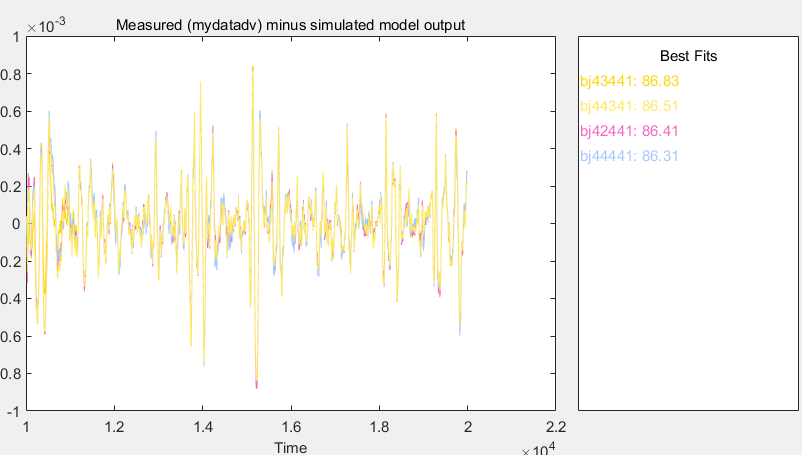

#### 3.7 Gráfico de validación de las salidas temporales

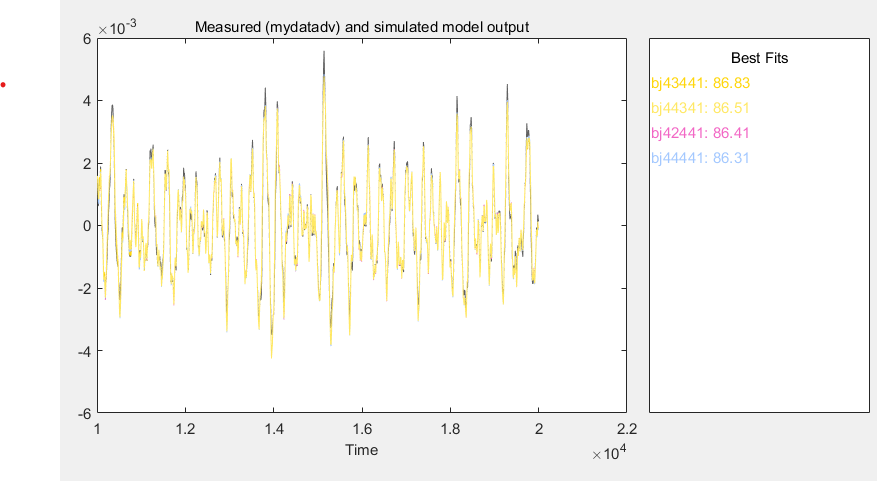

### 3.8 Grafico de validacion residual

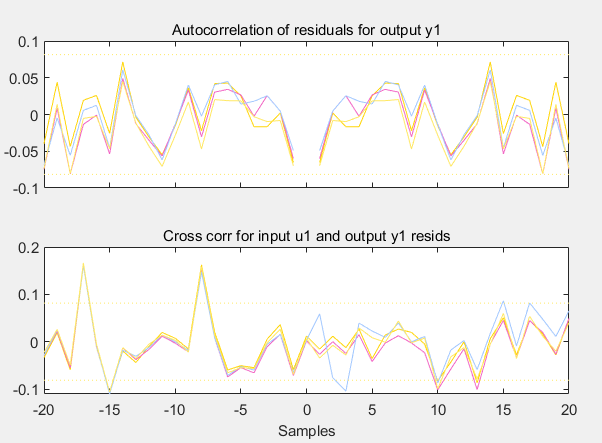

### 3.9 Gráfico de validación con la entrada escalón y las estructuras más representativas.

### 3.10 Gráfico de validación con la entrada sinusoidal y las estructuras más representativas.

### 3.11 Mejor modelo con los intervalos de confianza de cada parámetro y el gráfico de polos y ceros.

El mejor modelo estimado, tiene una estructura  Box-Jenkins (BJ)43441:


$$y(t)= \frac{B(z)}{A(z)}u(t) +\frac{C(z)}{D(z)}e(t)$$



$$
   \[
   B(z) = 0.003 \, (\pm 0.00002) z^{-1} + 0.001 \, (\pm 0.0004) z^{-2} - 0.003 \, (\pm 0.0002) z^{-3} - 0.0015 \, (\pm 0.0002) z^{-4}
   \]$$



$$  \[
   A(z) = 1 \, (\pm 0.1) - 1.1 \, (\pm 0.1) z^{-1} - 0.6 \, (\pm 0.2) z^{-2} + 0.9 \, (\pm 0.1) z^{-3} - 0.1 \, (\pm 0.02) z^{-4}
   \]$$



$$\[
   C(z) = 1 \, (\pm 0.07) - 2.4 \, (\pm 0.1) z^{-1} + 1.8 \, (\pm 0.1) z^{-2} - 0.5 \, (\pm 0.06) z^{-3}
   \]$$



$$\[
   D(z) = 1 \, (\pm 0.05) - 3.5 \, (\pm 0.1) z^{-1} + 4.8 \, (\pm 0.1) z^{-2} - 3 \, (\pm 0.1) z^{-3} + 0.7 \, (\pm 0.04) z^{-4}
   \]$$


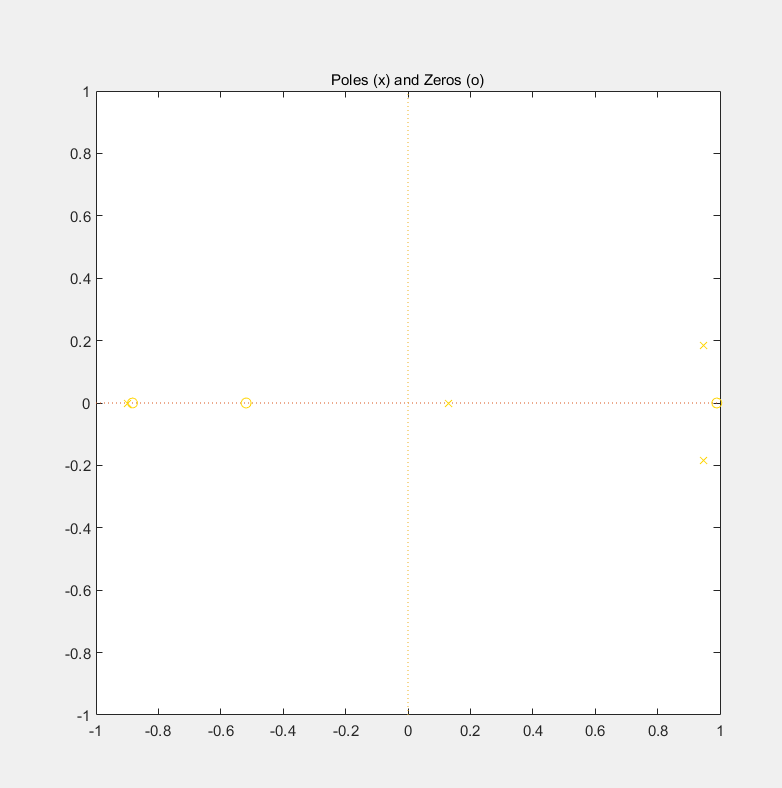

### 3.12 Pantallazo legible de la interfaz gráfica del System Identification Toolbox de MATLAB con todos los datos y resultados más representativos.

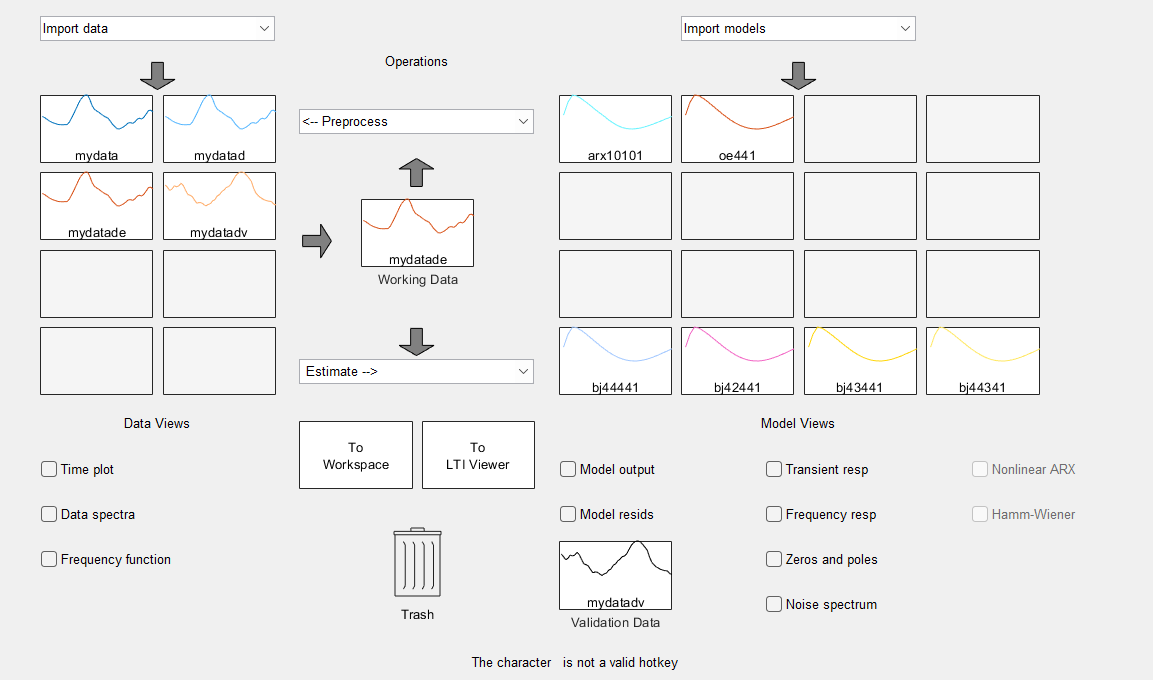

### 3.13 algortimo gradiente decendente

## 4. DISCUSIÓN

En esta sección, se abordan detalladamente los resultados obtenidos en la sección anterior, proporcionando un análisis exhaustivo para cada uno de ellos. Se exploran las implicaciones, patrones emergentes y cualquier correlación significativa que pueda arrojar luz sobre los hallazgos, contribuyendo así a una comprensión más completa y matizada de los datos recopilados**.**

### 4.1 Vereficacion del Codigo 

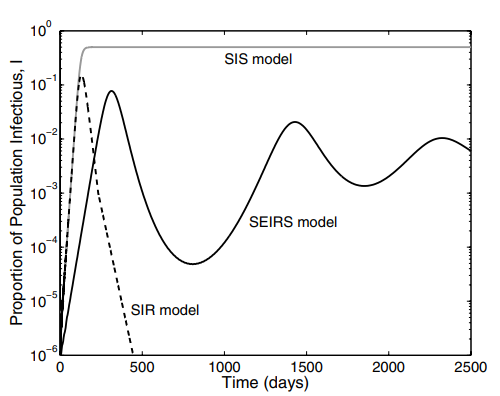

#### figura 3

La figura 3 nos muestra el comportamiento esperado de la poblacion de infectados en el modelo SEIRS (Curva negra) al comparar esta grafica con la generada por el modelo en la seccion 3.1 podemos obsevar que ambas curvas se corresponden, con esto podemos verificar que el modelo implementado se comporta de forma correcta.

### 4.2 Cambio entrada 

- **Entrada escalonada:**En el día 500 de la infección, se observa un brusco aumento en la población infectada, coincidiendo con un cambio repentino en el parámetro β del modelo epidemiológico. Este cambio sugiere la posible aparición o mutación de una cepa más contagiosa del patógeno. Además, el aumento en el número de infectados conduce a una convergencia más rápida de la población infectada. Esto se atribuye a la mayor tasa de transmisión de la nueva cepa, que acelera la propagación de la enfermedad y, en consecuencia, la velocidad a la que la población infectada alcanza su punto máximo.

- **Entrada sinusoidal:**El comportamiento estacionario representado por la onda sinusoidal indica que después del pico inicial, la población infectada disminuirá significativamente, lo que puede interpretarse como el declive del brote de la enfermedad en el escenario base. Sin embargo, es importante tener en cuenta que, aunque la cantidad de individuos infectados disminuirá, la enfermedad no se erradica por completo en el corto plazo. Es posible que haya fluctuaciones o pequeños repuntes en el número de casos, dependiendo de varios factores como las medidas de control implementadas y la inmunidad de la población.

- **Entrada pulso: **los pulsos que simulan cuarentenas periódicas, donde la población es sometida a períodos de restricción. En un año hipotético, por ejemplo, se establecen 23 días de cuarentena y 27 días sin restricciones. Se observa que estas cuarentenas son efectivas, ya que durante los períodos de restricción, la población infectada disminuye notablemente. Este patrón demuestra la importancia de las cuarentenas en la contención de la propagación de patógenos infecciosos y, en última instancia, en la salvaguarda de vidas. La reducción en el número de infectados durante los períodos de cuarentena indica que estas medidas son eficaces para controlar la transmisión del virus y evitar una mayor propagación de la enfermedad. 

### 4.3 Varaiacion de Parametros

#### 4.3.1 Soluciones cambiando ν

Para valores más pequeños de `ν`, que representan la tasa de pérdida de inmunidad, la población experimentará valles más pronunciados en la curva de susceptibles. Esto se debe a que los individuos recuperados retienen su inmunidad por más tiempo, lo que significa que menos individuos regresan al compartimento susceptible. Como resultado, la población susceptible tarda más en estabilizarse durante la fase de recuperación de un brote de enfermedad.

#### 4.3.2 Soluciones  cambiando γ

Cuando `ν` es pequeño y γ aumenta, muchos individuos se recuperan simultáneamente, lo que provoca una disminución brusca de la población infectada y un aumento repentino de la población recuperada. Este rápido cambio puede prolongar el tiempo necesario para que la población se estabilice, ya que la transición de individuos desde el estado infectado al recuperado ocurre de manera rápida.

## 5. Referencias

- [1]       K. Rock, S. Brand, J. Moir, and M. J. Keeling, ‘Dynamics of infectious diseases’, Reports on Progress in Physics, vol. 77, no. 2, p. 026602, Jan. 2014.

- [2]  O. N. Bjørnstad, K. Shea, M. Krzywinski, and N. Altman, ‘The SEIRS model for infectious disease dynamics’, Nature Methods, vol. 17, no. 6, pp. 557–558, Jun. 2020.

- [3]  T. Tomé and M. de Oliveira, ‘Susceptible-infected-recovered and susceptible-exposed-infected models’, J. Phys. J. Phys. A: Math. Theor, vol. 16750, 03 2011.

- [4]        Bill & Melinda Gates Foundation. “SEIR and SEIRS Models — HIV Model Documentation.” *Docs.idmod.org*, docs.idmod.org/projects/emod-hiv/en/latest/model-seir.html. Accessed 14 Apr. 2024.